% timeseries에서 시간 데이터 추출 후 변환
timeData = out.loadcellandpos.Time;
LoadcellData = out.loadcellandpos.Data(:,1);
DisplacementData = out.loadcellandpos.Data(:,2);
TactilesensorData = out.loadcellandpos.Data(:,3);
timeVector = seconds(timeData);  % 초 단위로 변환

% timetable 생성
data1 = timetable(timeVector, LoadcellData, 'VariableNames', {'LoadcellData'});
data2 = timetable(timeVector, DisplacementData, 'VariableNames', {'DisplacementData'});
data3 = timetable(timeVector, TactilesensorData, 'VariableNames', {'TactilesensorData'});

% 1587행부터 3167행까지의 데이터만 선택
% data1 = data1(1587:3167,:);
% data2 = data2(1587:3167,:);

% Force 계산 (LoadcellData * -5)
Initial_force= mean(data1.LoadcellData(1:50));
Force = (data1.LoadcellData-Initial_force) * -5;

Initial_Displacement = mean(data2.DisplacementData(1:50));
Displacement =(data2.DisplacementData-Initial_Displacement)*-2;

Initial_Sensor = mean(data3.TactilesensorData(1:50));
Sensor = data3.TactilesensorData;


% Force threshold 필터링
% Force_threshold_upper = 5.0;
% Force_threshold_lower = 0.05;
% valid_indices1 = Force >= Force_threshold_lower;
% valid_indices2 = Force <= Force_threshold_upper;
% valid_indices = valid_indices1 & valid_indices2;

Sensor_threshold_upper =2110;
Sensor_threshold_lower = Initial_Sensor;
valid_indices1 = Sensor >= Sensor_threshold_lower;
valid_indices2 = Sensor <= Sensor_threshold_upper;
valid_indices = valid_indices1 & valid_indices2;



% 필터링된 데이터만 사용
 Force_filtered = Force(valid_indices);
 Displacement_filtered = Displacement(valid_indices);
 Sensor_filtered = Sensor(valid_indices);
 timeVector_filtered = data1.timeVector(valid_indices);



% fprintf('전체 데이터 포인트: %d개\n', length(Force));
% fprintf('Force >= %.3f 인 데이터 포인트: %d개\n', Force_threshold_upper, length(Force_filtered));
% fprintf('데이터 사용률: %.1f%%\n', (length(Force_filtered)/length(Force))*100);

% Force vs Sensor 그래프 그리기 (필터링된 데이터만 사용)
figure;
plot(Sensor_filtered, Force_filtered, 'b-', 'LineWidth', 1.5);
xlabel('Sensor (value)');
ylabel('Force (N)');
% title(sprintf('Force vs SensorData'));
grid on;

% 선형 피팅을 통한 stiffness 계산 (필터링된 데이터만 사용)
p = polyfit(Sensor_filtered, Force_filtered, 1)  % 1차 다항식 피팅

p =     0.0026   -3.0617


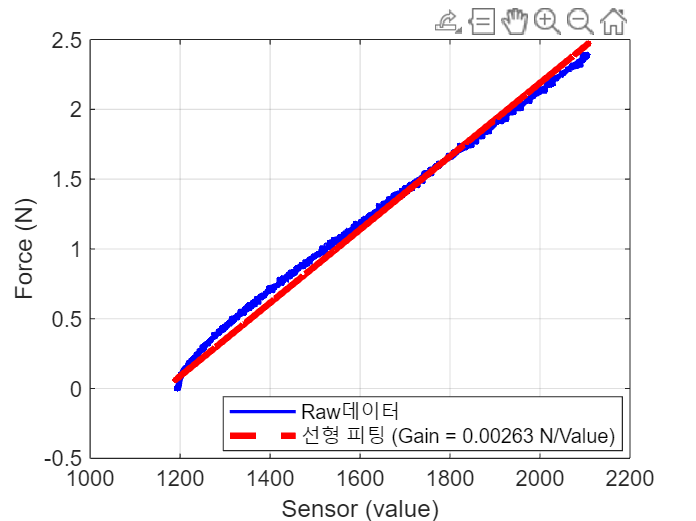

stiffness = p(1);  % 기울기가 stiffness

% 피팅된 직선 추가
hold on;
fitted_force = polyval(p, Sensor_filtered);
plot(Sensor_filtered, fitted_force, 'r--', 'LineWidth', 3);
legend('Raw데이터', sprintf('선형 피팅 (Gain = %.5f N/Value)', stiffness), 'Location', 'best');


% 결과 출력
fprintf('계산된 Gain: %.5f N/mm\n', stiffness);

계산된 Gain: 0.00263 N/mm


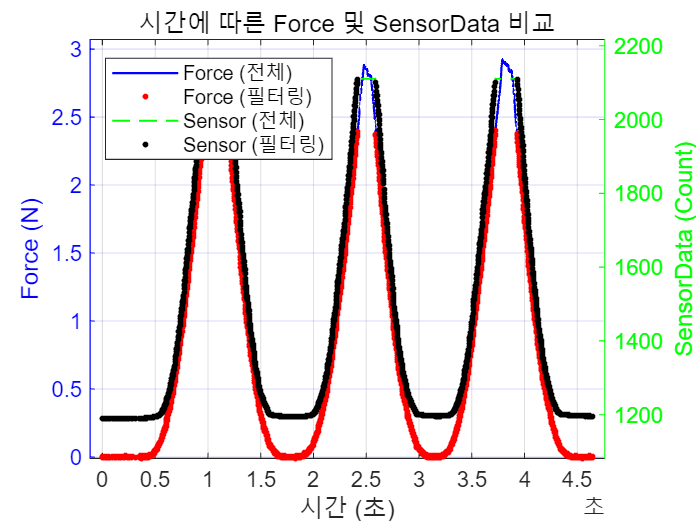


% --- 추가 분석 그래프: Force (좌측 Y축) vs. SensorData (우측 Y축) ---
figure; % 새로운 Figure 생성

% 1. Force 데이터를 좌측 Y축에 그리기
yyaxis left;
plot(data1.timeVector, Force, 'b-', 'LineWidth', 1.0, 'DisplayName', 'Force (전체)');
hold on;
plot(timeVector_filtered, Force_filtered, 'r.', 'MarkerSize', 8, 'DisplayName', 'Force (필터링)');

% 좌측 축 설정
xlabel('시간 (초)');
ylabel('Force (N)', 'Color', 'b');
ylim([min(Force) max(Force)*1.05]); % Force 범위 자동 설정
ax = gca;
ax.YColor = 'b'; % 왼쪽 축 색상을 파란색(Force)으로 설정

% 2. SensorData 데이터를 우측 Y축에 그리기
yyaxis right;
plot(data3.timeVector, Sensor, 'g--', 'LineWidth', 1.0, 'DisplayName', 'Sensor (전체)');
plot(timeVector_filtered, Sensor_filtered, 'k.', 'MarkerSize', 8, 'DisplayName', 'Sensor (필터링)'); % 검은 점

% 우측 축 설정
ylabel('SensorData (Count)', 'Color', 'g');
ylim([min(Sensor) max(Sensor)*1.05]); % SensorData 범위 자동 설정
ax.YColor = 'g'; % 오른쪽 축 색상을 초록색(Sensor)으로 설정

% 3. 최종 설정
title('시간에 따른 Force 및 SensorData 비교');
grid on;

% 두 축의 모든 범례 항목을 표시
legend('show', 'Location', 'best');


% 상관계수 계산은 기존 코드를 그대로 사용
R = corrcoef(Sensor_filtered,Force_filtered);
fprintf('시간 그래프에 대한 상관계수: %.4f\n', R(1,2));

시간 그래프에 대한 상관계수: 0.9962




% subplot(2,2,3);
% plot(Displacement, Force, 'b-', 'LineWidth', 0.5, 'DisplayName', '전체 데이터');
% hold on;
% plot(Sensor, Forc, 'ro', 'MarkerSize', 4, 'DisplayName', '필터링된 데이터');
% xlabel('Displacement (mm)'); ylabel('Force (N)'); title('Force vs Displacement (비교)');
% legend('show'); grid on;

% subplot(2,2,4);
% residuals = Force_filtered - fitted_force;
% plot(Displacement_filtered, residuals, 'ko');
% xlabel('Displacement (mm)'); ylabel('잔차 (N)'); title('피팅 잔차 (필터링된 데이터)'); grid on;
